# HW6

## Part 1: Blurring an Image

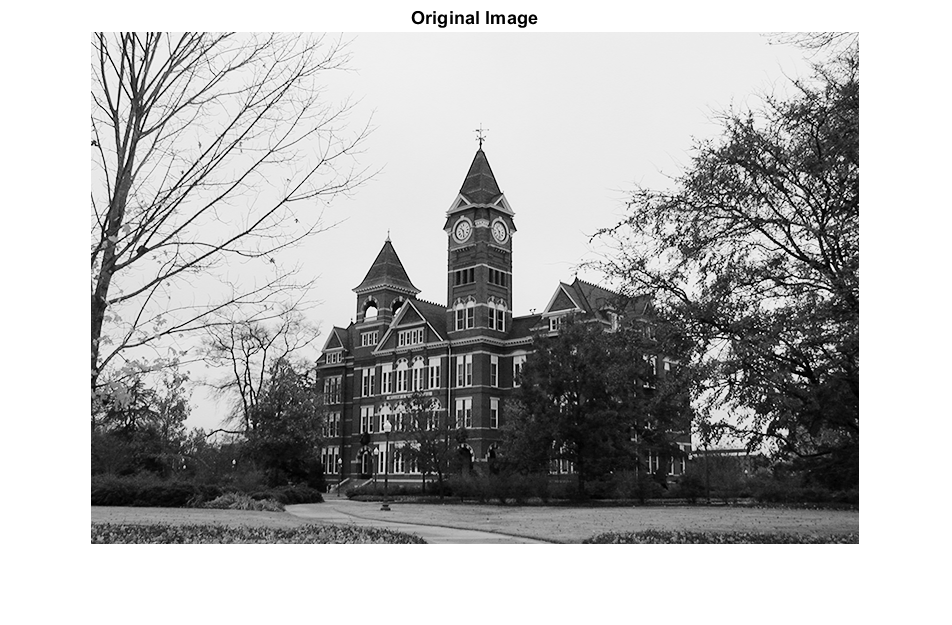

image = rgb2gray(imread('samford.png'));
ker = fspecial('disk', 6);

image_F = fft2(im2double(image));
ker_F = fft2(ker, size(image, 1), size(image, 2));
blurred_image = uint8(255 * real(ifft2(ker_F .* image_F)));
figure(1)
imshow(image)
title("Original Image")

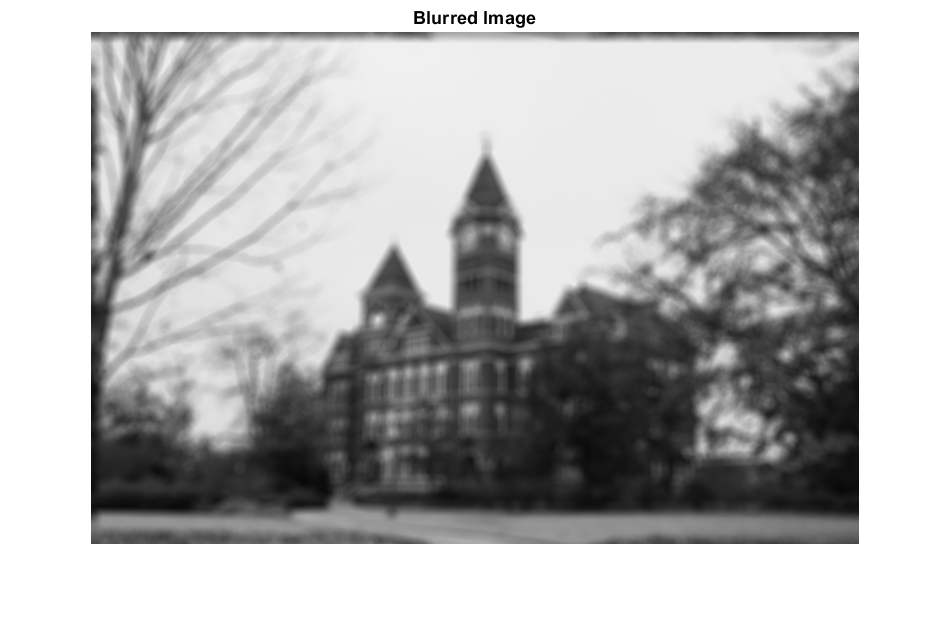

figure(2)
imshow(blurred_image)
title("Blurred Image")

## Part 2: Inverse Filtering

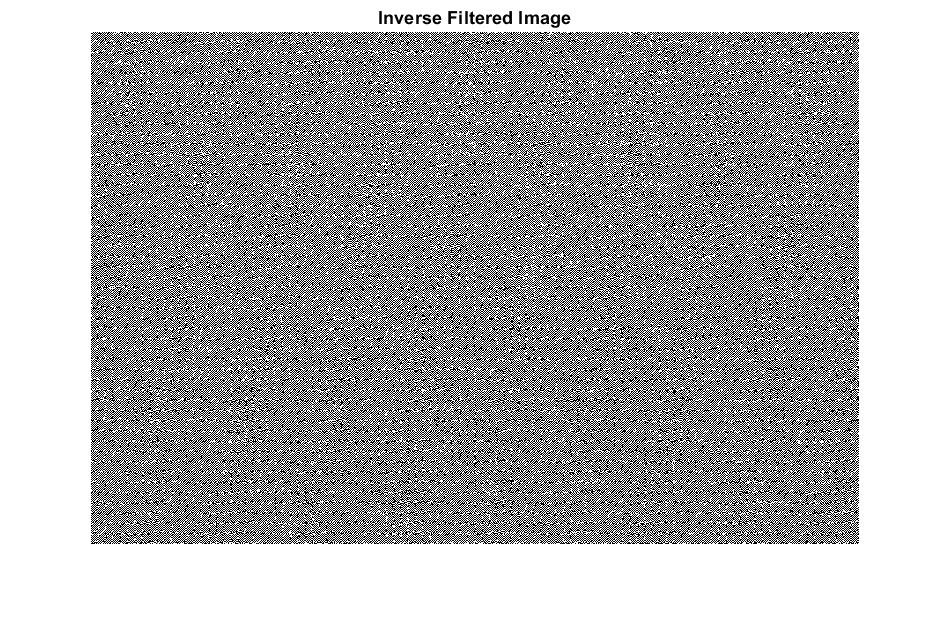

blurred_image_F = fft2(im2double(blurred_image));
ker_F = fft2(ker, size(blurred_image, 1), size(blurred_image, 2));

inverse_image = uint8(255 * real( ifft2( blurred_image_F ./ ker_F) ));
figure(3)
imshow(inverse_image)
title("Inverse Filtered Image")

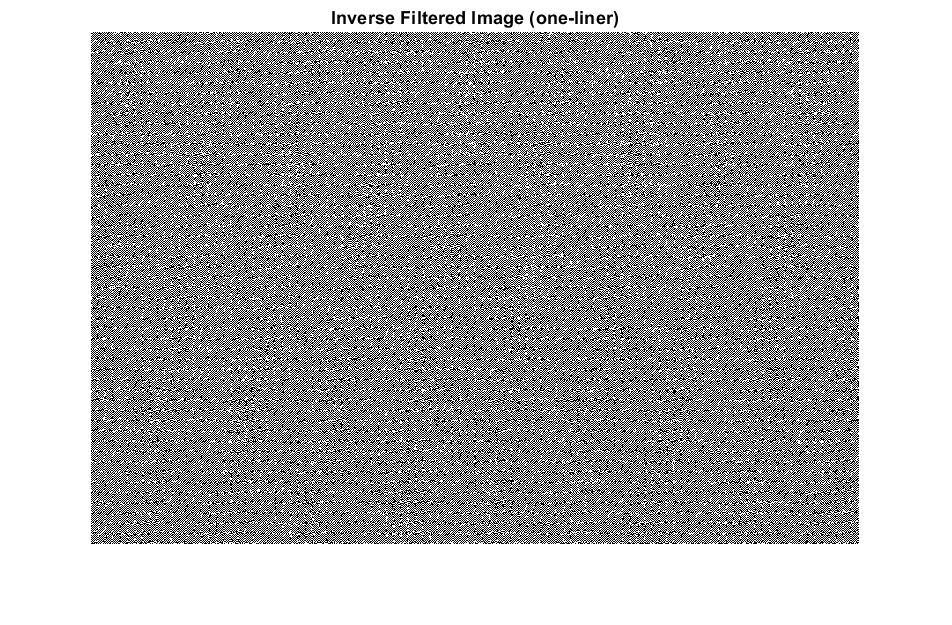


inverse_image_one_line = uint8(255 * real(...
    ifft2(...
    fft2(im2double(blurred_image)) ./ fft2(ker, size(blurred_image, 1), size(blurred_image, 2)))...
    ));

figure(4)
imshow(inverse_image_one_line)
title("Inverse Filtered Image (one-liner)");